clear all; close all;
A = 0.32345; B = -0.78743; C = 0.56532;
sign=1; %0-unsigned value, 1-signed value % sign
prec_i=1; %number of integer part bits (Nc) % one bit
prec_f=10; %number of fractional part bits (Nu) % ten bits
word = sign + prec_i + prec_f; % whole word

A_fix = fi(A,sign,word,prec_f);
B_fix = fi(B,sign,word,prec_f);
C_fix = fi(C,sign,word,prec_f);
A_double = double(A_fix);
B_double = double(B_fix);
C_double = double(C_fix);

sum_fix = (A_fix+B_fix);
Y_fix = sum_fix*C_fix;
Y_double = double(Y_fix)

Y_double = -0.2623


Y = (A+B);
Y = Y * C

Y = -0.2623


difference = abs(Y-Y_double)

difference = 1.2895e-05

bin(A_fix)

ans = '000101001011'

bin(B_fix)

ans = '110011011010'

bin(C_fix)

ans = '001001000011'

bin(sum_fix)

ans = '1111000100101'

Y_fix

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 25
        FractionLength: 20

bin(Y_fix)

ans = '1111110111100110110101111'

A = bin2fixed('000101001011', 1, 1, 10)

A = 0.3232

B = bin2fixed('110011011010', 1, 1, 10)

B = -0.7871

C = bin2fixed('001001000011', 1, 1, 10)

C = 0.5654


A_sum_B = A + B

A_sum_B = -0.4639

A_sum_B_vivado = bin2fixed('1111000100101', 1, 2, 10)

A_sum_B_vivado = -0.4639


AB_mult_C = A_sum_B * C

AB_mult_C = -0.2623


Mult_vivado = bin2fixed('1111110111100110110101111', 1, 4, 20)

Mult_vivado = -0.2623


diff = AB_mult_C - Mult_vivado

diff = 0

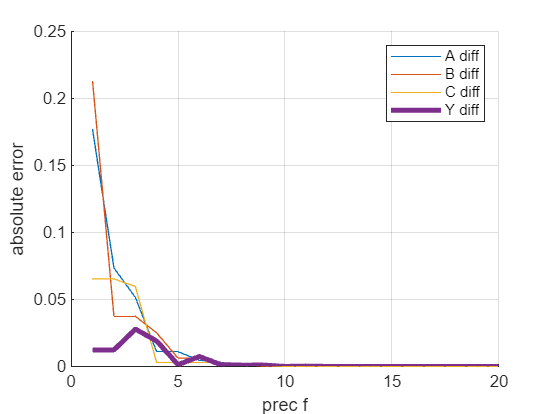

clear all; close all;
A = 0.32345; B = -0.78743; C = 0.56532;
Y = (A+B)*C;
prec_f = 1:20; %SET!!!
diff_A = []; diff_B = []; diff_C = []; diff_Y = [];
size_pf = size(prec_f);
for i=1:size_pf(2)
    A_fix = fi(A,1,prec_f(i)+2,prec_f(i));
    B_fix = fi(B,1,prec_f(i)+2,prec_f(i));
    C_fix = fi(C,1,prec_f(i)+2,prec_f(i));
    Y_fix = (A_fix+B_fix)*C_fix;
    diff_A(end+1)=abs(A-double(A_fix));
    diff_B(end+1)=abs(B-double(B_fix));
    diff_C(end+1)=abs(C-double(C_fix));
    diff_Y(end+1)=abs(Y-double(Y_fix));
end
figure
hold on
plot(prec_f,diff_A,'DisplayName','A diff')
plot(prec_f,diff_B,'DisplayName','B diff')
plot(prec_f,diff_C,'DisplayName','C diff')
plot(prec_f,diff_Y,'DisplayName','Y diff','LineWidth',3)
xlabel('prec f'), ylabel('absolute error')
legend(), grid(), hold off

% wybieram pracyzję 10 po przecinku


function value = bin2fixed(bin_str, sign, prec_i, prec_f)
    word = sign + prec_i + prec_f; % Obliczenie długości słowa

    % Konwersja binarnego stringa na liczbę dziesiętną
    int_value = bin2dec(bin_str);
    
    % Jeśli liczba jest podpisana (signed), sprawdzamy znak
    if sign == 1 && bin_str(1) == '1'
        % Ujemne liczby w notacji znak-moduł (two's complement)
        int_value = int_value - 2^word;
    end
    
    % Obliczenie wartości fixed-point
    value = int_value / 2^prec_f;
end